# **RRA**

# **LAB 3**

## **Stabilizarea sistemelor MIMO + Youla pe MIMO**

### **Stabilitate BIBO (Bounded Input Bounded Output)**

Ce inseamna acest fel de stabilitate? Daca am o intrare marginita u $||u||_{\infty } <\infty$, atunci am un $\Sigma$ care imi produce o iesire marginita y $||y||_{\infty } <\infty$


$$y=\Sigma \left(u\right),\textrm{unde}\;y\;\textrm{este}\;\textrm{raspuns}\;\textrm{fortat}$$


Sa luam reprezentarea pe stare:

$\left\lbrace \begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}+\textrm{Du}
\end{array}\right.\Rightarrow \left\lbrace \begin{array}{l}
Y\left(s\right)=G\left(s\right)U\left(s\right)\\
G\left(s\right)=C\left(s\right){\left(\textrm{sI}-A\left(s\right)\right)}^{-1} B\left(s\right)+D\left(s\right)
\end{array}\right.$. Polii lui $G\left(s\right)\in {\mathbb{C}}_-$. Daca sistemul este **minimal**, atunci acesti poli coincid cu $\Lambda \left(A\right)$

### Stabilitate interna asimptotica


$$\left\lbrace \begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}+\textrm{Du}
\end{array}\right.$$


Daca $u\left(t\right)\equiv 0\Rightarrow x_l \left(t\right)=e^{\textrm{At}} x_0 ,\textrm{unde}\;x_l \;\textrm{este}\;\textrm{raspuns}\;\textrm{liber}$. De asemenea, $\lim_{t\to \infty } ||x_l \left(t\right)||_p =0,\forall x_0 \in {\mathbb{R}}^n \;\textrm{si}\;p\in \mathbb{N}-\left\lbrace 0\right\rbrace \Leftrightarrow \Lambda \left(A\right)\in {\mathbb{C}}_-$

In acest sens, avem schema urmatoare:


$$\left\lbrace \begin{array}{l}
\textrm{Stabilitate}\;\textrm{interna}\Rightarrow \textrm{stabil}\;\textrm{BIBO}\\
\textrm{Stabilitate}\;\textrm{BIBO}+\textrm{controlabilitate}\;\textrm{si}\;\textrm{observabilitate}\Rightarrow \textrm{Stabilitate}\;\textrm{interna}
\end{array}\right.$$


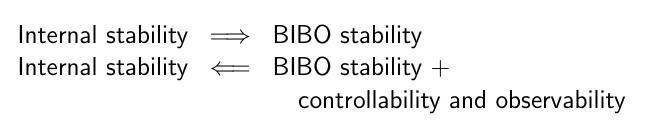

**De ce este asa?** Cand ma uit la stabilitate interna, ma uit la valorile proprii ale lui A $\Lambda \left(A\right)$care cuprind *atat polii lui *$G\left(s\right)$, cat si partile *necontrolabile* (cele unde nu poate "ajunge") si *neobservabile* (ce nu poate "vedea")

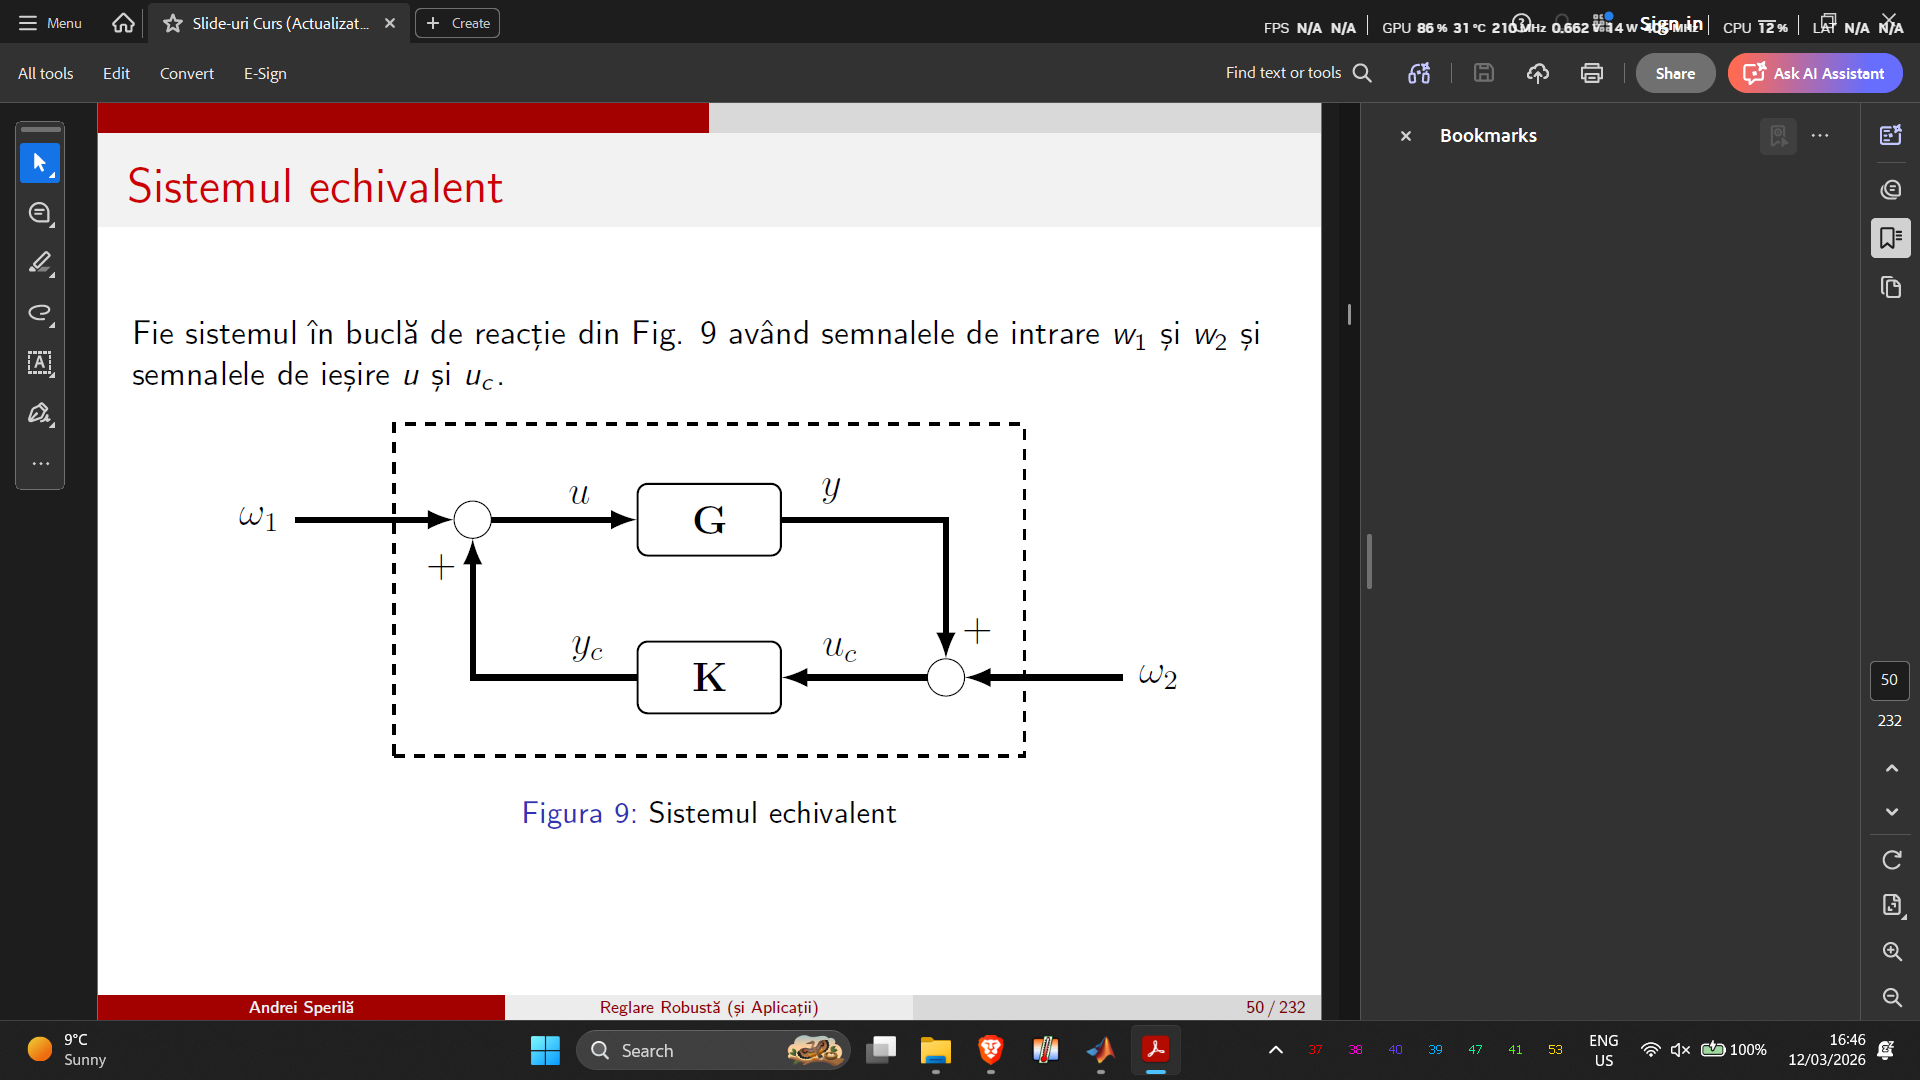

si am asa: $\left\lbrace \begin{array}{l}
G:\left\lbrace \begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}+\textrm{Du}
\end{array}\right.\;\\
K:\left\lbrace \begin{array}{l}
\dot{x_k } =A_k x_k +B_k u_k \\
y_k =C_k x_k +D_k u_k 
\end{array}\right.
\end{array}\right.$.  In acest sens, avem $\left\lbrace \begin{array}{l}
\dot{\left\lbrack \begin{array}{c}
x\\
x_k 
\end{array}\right\rbrack } =A_{\textrm{cl}} \left\lbrack \begin{array}{c}
x\\
x_k 
\end{array}\right\rbrack +B_{\textrm{cl}} \left\lbrack \begin{array}{c}
w_1 \\
w_2 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
y\\
y_k 
\end{array}\right\rbrack =C_{\textrm{cl}} \left\lbrack \begin{array}{c}
x\\
x_k 
\end{array}\right\rbrack +D_{\textrm{cl}} \left\lbrack \begin{array}{c}
w_1 \\
w_2 
\end{array}\right\rbrack 
\end{array}\right.$. Noi trebuie sa aflam $K=?$ astfel incat $\Lambda \left(A_{\textrm{cl}} \right)\in {\mathbb{C}}_-$. In acest sens $G_{\textrm{cl}} \left(s\right)=C_{\textrm{cl}} \left(s\right){\left(\textrm{sI}-A_{\textrm{cl}} \left(s\right)\right)}^{-1} B_{\textrm{cl}} \left(s\right)+D_{\textrm{cl}} \left(s\right)$ este matrice de transfer stabila $\left(\textrm{cu}\;\textrm{poli}\in {\mathbb{C}}_- \right)$

**Acest sistem este bine definit in sens strict **$\Leftrightarrow \forall \left\lbrace \begin{array}{l}
I-K\left(\infty \right)G\left(\infty \right)\\
I-G\left(\infty \right)K\left(\infty \right)\\
\left\lbrack \begin{array}{cc}
I & -K\left(\infty \right)\\
-G\left(\infty \right) & I
\end{array}\right\rbrack 
\end{array}\right.$ **sa fie inversabila. Una din cele 2 este suficient, caci sunt echivalente intre ele**

### O chestie smechera

Daca $G\;\textrm{si}\;K$ sunt ***MINIM Stabilizabile si Detectabile,*** atunci stabilizarea in bucla inchisa **este echivalenta cu** stabiizarea interna asimptotica in bucla inchisa

### **Remarca:**

Rezolvarea stabilizarii este grea, dar echivalenta cu probleme usoare de stabilizare I/O

#### Acum sa trecem in Lapalce

$\left\lbrace \begin{array}{l}
y=G\left(w_1 +y_k \right)\\
y_k =K\left(w_2 +y\right)
\end{array}\right.$. Acum vom face 2 inlocuiri si anume $y_k \to y\;\textrm{si}\;y\to y_k$. In acest sens, avem:

$\left\lbrace \begin{array}{l}
y={\textrm{Gw}}_1 +{\textrm{GKw}}_2 +\textrm{GKy}\\
y_k ={\textrm{Kw}}_2 +{\textrm{KGw}}_1 +{\textrm{KGy}}_k 
\end{array}\right.\Rightarrow \left\lbrace \begin{array}{l}
y\left(I-\textrm{GK}\right)={\textrm{Gw}}_1 +{\textrm{GKw}}_2 \\
y_k \left(I-\textrm{KG}\right)={\textrm{Kw}}_2 +{\textrm{KGw}}_1 
\end{array}\right.\ldotp$ Pentru buna definire, avem nevoie de $\left\lbrack \begin{array}{cc}
I & -D\\
-D_k  & I
\end{array}\right\rbrack$ sa fie inversabila. Acum sa reluam calculele:


$$\left\lbrace \begin{array}{l}
y={\left(I-\textrm{GK}\right)}^{-1} {\textrm{Gw}}_1 +{\left(I-\textrm{GK}\right)}^{-1} {\textrm{GKw}}_2 \\
y_k ={\left(I-\textrm{KG}\right)}^{-1} {\textrm{Kw}}_2 +{\left(I-\textrm{KG}\right)}^{-1} {\textrm{KGw}}_1 
\end{array}\right.\Rightarrow \left\lbrace \begin{array}{l}
y={\left(I-\textrm{GK}\right)}^{-1} {\textrm{Gw}}_1 +{\left(I-\textrm{GK}\right)}^{-1} {\textrm{GKw}}_2 \\
y_k ={K\left(I-\textrm{GK}\right)}^{-1} w_1 +{K\left(I-\textrm{GK}\right)}^{-1} {\textrm{Gw}}_2 
\end{array}\right.$$


In acest sens, vrem $\left\lbrace \begin{array}{l}
{\left(I-\textrm{GK}\right)}^{-1} G\\
{\left(I-\textrm{GK}\right)}^{-1} \textrm{GK}\\
{K\left(I-\textrm{GK}\right)}^{-1} \\
{K\left(I-\textrm{GK}\right)}^{-1} G
\end{array}\right.\Rightarrow \left\lbrace \begin{array}{l}
{\left(I-\textrm{GK}\right)}^{-1} G\\
{\left(I-\textrm{GK}\right)}^{-1} \left(\textrm{GK}-I+I\right)\\
{K\left(I-\textrm{GK}\right)}^{-1} \\
{K\left(I-\textrm{GK}\right)}^{-1} G
\end{array}\right.\Rightarrow$

$\left\lbrace \begin{array}{l}
{\left(I-\textrm{GK}\right)}^{-1} G\\
{\left(I-\textrm{GK}\right)}^{-1} -I\\
{K\left(I-\textrm{GK}\right)}^{-1} \\
{K\left(I-\textrm{GK}\right)}^{-1} G
\end{array}\right.$sa fie stabile. Mai precis, $\left\lbrack \begin{array}{c}
K\\
I
\end{array}\right\rbrack {\left(I-\textrm{GK}\right)}^{-1} \left\lbrack \begin{array}{cc}
G & I
\end{array}\right\rbrack$ sa fie stabila, cu poli in ${\mathbb{C}}_-$. Asta se mai numeste si **"The gang of four" (zic sa se faca film despre asta, o sa propun asta)**

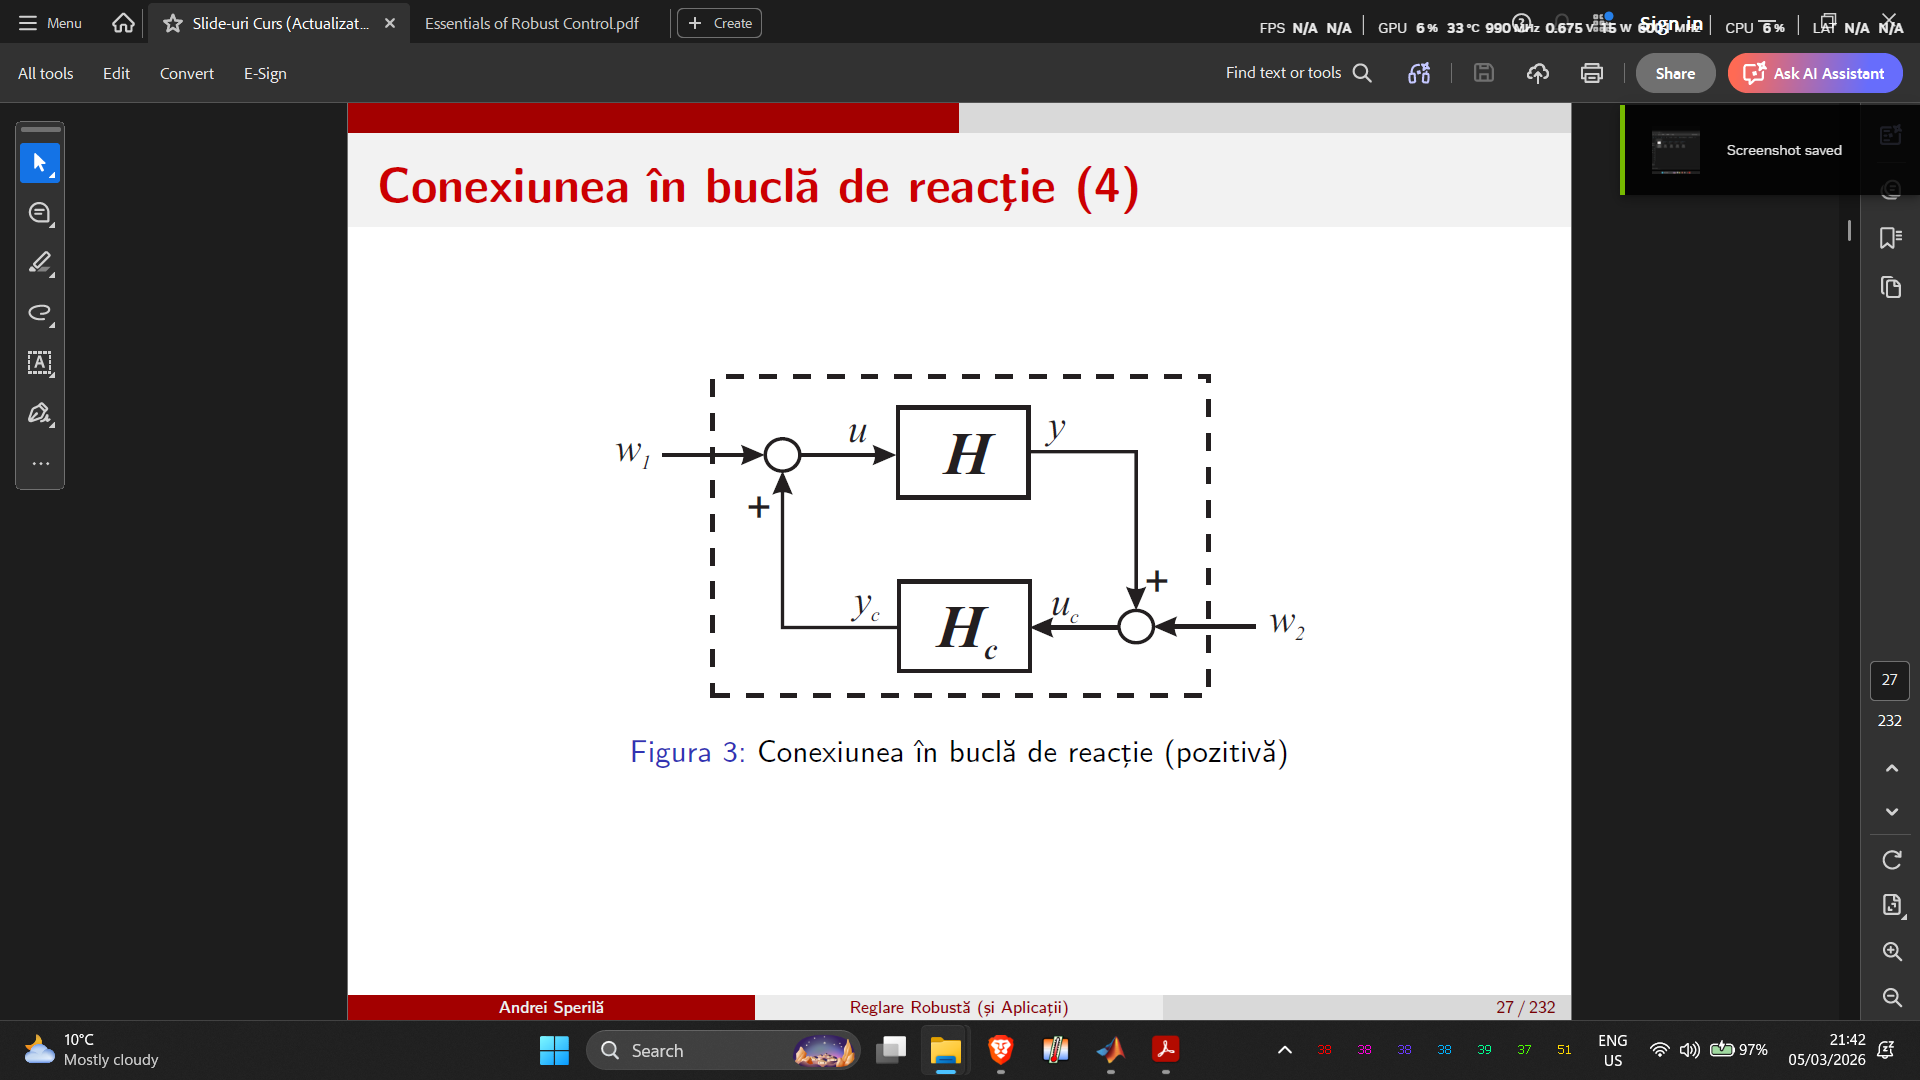  stabila $\to$

 (laplace) stabila

**Fie **$n_G \;\textrm{si}\;n_K$** numarul de poli instabili **$\left({\mathbb{C}}_+ \right)$** ai lui G respectiv K. Sistemul in bulca de reactie este intern stabil **$\Leftrightarrow$** este bine definit in sens strict si **$\left\lbrace \begin{array}{l}
\textrm{numarul}\;\textrm{de}\;\textrm{poles}\left(G\left(s\right)K\left(s\right)\right)=n_G +n_K \\
{\left(I-\textrm{GK}\right)}^{-1} \;\textrm{este}\;\textrm{in}\;\mathcal{R}{\mathcal{H}}_{\infty } 
\end{array}\right.$. Prima conditie ne spune ca **nu exista simplificari poli-zero instabile **cand se formenaza produsul $\textrm{GK}$, iar a doua conditie ne spune ca $I-\textrm{GK}$ **nu are zerouri instabile**

Atunci cand $G\;\textrm{si}\;/\;\textrm{sau}\;K$ sunt stabile in $\mathcal{R}{\mathcal{H}}_{\infty }$, stabilitatea interna a buclei se poate determina usor$\left\lbrace \begin{array}{l}
G\in \mathcal{R}{\mathcal{H}}_{\infty } ,\textrm{sistemul}\;\textrm{este}\;\textrm{intern}\;\textrm{stabil}\Leftrightarrow {K\left(I-\textrm{GK}\right)}^{-1} \in \mathcal{R}{\mathcal{H}}_{\infty } \\
K\in \mathcal{R}{\mathcal{H}}_{\infty } ,\textrm{sistemul}\;\textrm{este}\;\textrm{intern}\;\textrm{stabil}\Leftrightarrow {G\left(I-\textrm{KG}\right)}^{-1} \in \mathcal{R}{\mathcal{H}}_{\infty } \\
G\in \mathcal{R}{\mathcal{H}}_{\infty } \;\textrm{si}\;K\in \mathcal{R}{\mathcal{H}}_{\infty } ,\textrm{sistemul}\;\textrm{este}\;\textrm{intern}\;\textrm{stabil}\Leftrightarrow {\left(I-\textrm{GK}\right)}^{-1} \in \mathcal{R}{\mathcal{H}}_{\infty } 
\end{array}\right.$

## Acum intram in prima parte din laborator

clear
close all
clc

s = tf('s');

A = randi(9,4,4)

A =      4     8     7     3
     4     4     2     6
     7     2     4     5
     6     1     5     2



eig(A)

ans =   17.8357 + 0.0000i
  -1.4752 + 1.2744i
  -1.4752 - 1.2744i
  -0.8852 + 0.0000i



B = randi(9,4,3)

B =      8     5     2
     1     1     8
     3     4     3
     3     1     6



C = randi(9,2,4)

C =      9     7     4     1
     4     7     6     9



D = randi(9,2,3)

D =      2     8     7
     3     5     4


Vad daca este stabilizabil + detectabil

Pc = ctrb(A,B);

disp('Rangul matricii de ctrb');

Rangul matricii de ctrb


disp(rank(Pc))

     4




Po = obsv(A,C);

disp('Rangul matricii de obsv');

Rangul matricii de obsv


disp(rank(Po))

     4



Sistem minimal, este bine, pot gasi un K pentru care stabilizez pe G

## Youla pe MIMO. Devine interesant

**Sa ne readucem aminte la SISO** cum arata G-ul: $G=\frac{N}{M}$, unde $M\;\textrm{si}\;N$ sunt stabile si coprime intre ele. **Mod de construire: **stim ca $\sigma n\le \sigma m=k\;\textrm{si}\;G=\frac{n}{m}$. In acest sens, $\left\lbrace \begin{array}{l}
N=\frac{n}{{\left(s+1\right)}^k }\\
M=\frac{m}{{\left(s+1\right)}^k }
\end{array}\right.$. De asemenea, $\exists X,Y\in \mathcal{S}$ astfel incat$\textrm{NX}+\textrm{MY}=1$, egalitatea lui Bezout. K in forma generica este $K=\left\lbrace \frac{X+\textrm{MQ}}{Y+\textrm{NQ}}|\;Q\in \mathcal{S}\right\rbrace$

**La MIMO incep sa se complice lucrurile:** $\left\lbrace \begin{array}{l}
\textrm{In}\;\textrm{loc}\;\textrm{de}\;\textrm{functii}\;\textrm{de}\;\textrm{transfer}\;\textrm{am}\;\textrm{Matrice}\;\textrm{de}\;\textrm{Transfer}\\
\textrm{MT}\;\textrm{nu}\;\textrm{au}\;\textrm{proprietatea}\;\textrm{ce}\;\textrm{comutativitate}\;\textrm{la}\;\textrm{inmultire},\textrm{critica}\;\textrm{la}\;\textrm{scrierea}\;\textrm{factorizarilor}\\
\textrm{Necesita}\;\textrm{dezvoltata}\;o\;\textrm{teorie}\;\textrm{de}\;\textrm{factorizari}\;\textrm{coprime}\;\textrm{peste}\;\textrm{inelul}\;\textrm{matricelor}\;\textrm{polinomiale}/\textrm{rationale}\\
\textrm{Chiar}\;\textrm{si}\;\textrm{cum}\;\textrm{teoria}\;\textrm{de}\;\textrm{divizibilitate}\;\textrm{peste}\;\textrm{matrici}\;\textrm{polinomiale}/\textrm{rationale}\;\textrm{stabile}\;\textrm{nu}\;\textrm{este}\;\textrm{placut}
\end{array}\right.$

Macar avem si vesti bune: $\left\lbrace \begin{array}{l}
\exists \;o\;\textrm{identitate}\;\textrm{Bezout}\;\textrm{peste}\;\textrm{matriec}\;\textrm{polinomiale}\;\textrm{sau}\;\textrm{rationale}\\
\textrm{Parametrizare}\;\textrm{Youla}\;\textrm{se}\;\textrm{poate}\;\textrm{scrie}\;\textrm{din}\;\textrm{nou}\;\textrm{in}\;\textrm{raport}\;\textrm{cu}\;\textrm{ea}
\end{array}\right.$

Din cate se poate observa, nu mai avem factotizare coprima $\in \mathcal{S}$. O sa avem nevoie de factorizari la stanga si dreapta

#### Ok, cum definim coprimitatea la MT (rationale)

Fie 2 matrici $M,N\in \mathcal{R}{\mathcal{H}}_{\infty }$. Acestea sunt coprime daca au acelasi numar de coloane si $\exists \tilde{X} ,\tilde{Y} \in \mathcal{R}{\mathcal{H}}_{\infty }$ astfel incat sa aiba loc $\left\lbrack \begin{array}{cc}
\tilde{Y}  & -\tilde{X} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
M\\
N
\end{array}\right\rbrack =\tilde{Y} M-\tilde{X} N=I$, iar $G={\textrm{NM}}^{-1}$

Fie alte 2 matrici $\tilde{M} ,\tilde{N} \in \mathcal{R}{\mathcal{H}}_{\infty }$. Acestea sunt coprime daca au acelasi numar de linii si $\exists X,Y\in \mathcal{R}{\mathcal{H}}_{\infty }$ astfel incat ca aiba loc $\left\lbrack \begin{array}{cc}
\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-X\\
Y
\end{array}\right\rbrack =\tilde{M} Y-\tilde{N} X=I$, iar $G={\tilde{M} }^{-1} \tilde{\;N}$

$G$ are factorilzare** dublu coprima** daca au loc $G={\textrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N}$, iar $N,M,X,Y,\tilde{N} ,\tilde{M} ,\tilde{X} ,\tilde{Y}$ respecta $\left\lbrack \begin{array}{cc}
Y & -\tilde{X} \\
-N & \tilde{M} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =I$. Aceasta relatie spune mai mult decat factorizarile coprime la stanga si dreapta si identitatile Bezout corespunzatoare de corpimitate

Fie $\left\lbrace \begin{array}{l}
G={\textrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N} \\
K={\textrm{XY}}^{-1} ={\tilde{Y} }^{-1} \tilde{X} 
\end{array}\right.$ factorizari coprime la stanga si dreapta pentur sistem si regualtor.

Urmatoarele afirmatii sunt echivalente:

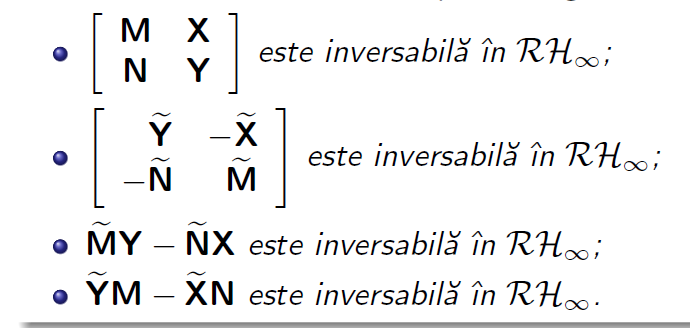

Sa ne readucem aminte cum arata clasa compenastoarelor la SISO:


$$K=\left\lbrace \frac{X+\textrm{MQ}}{Y+\textrm{NQ}}|\;Q\in \mathcal{S}\right\rbrace$$


#### Acum sa trecem la MIMO:

Pentru $G={\textrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N}$, clasa tuturor compensatoarelor **cu MT proprie** care stabilizeaza intern bucla de reactie este data de una din urmatoarele expresii **echivalente:**

$\left\lbrace \begin{array}{l}
K=\left(X+\textrm{MQ}\right){\left(Y+\textrm{NQ}\right)}^{-1} ,\textrm{unde}\;Q\in \mathcal{R}{\mathcal{H}}_{\infty } \;\textrm{cu}\;\det \left(Y+\textrm{NQ}\right)\left(\infty \right)\not= 0\\
K={\left(\tilde{Y} +Q\tilde{N} \right)}^{-1} \left(X+\textrm{MQ}\right),\textrm{unde}\;Q\in \mathcal{R}{\mathcal{H}}_{\infty } \;\textrm{cu}\;\det \left(\tilde{Y} +Q\tilde{N} \right)\left(\infty \right)\not= 0
\end{array}\right.$, iar $\left\lbrace \begin{array}{l}
X\;\textrm{si}\;Y\;\textrm{verifica}\;\textrm{Bezout}\;\tilde{M} Y-\tilde{X} N=I\\
\tilde{X} \;\textrm{si}\;\tilde{Y} \;\textrm{verifica}\;\textrm{Bezout}\;\tilde{Y} M-\tilde{X} N=I
\end{array}\right.$. Daca $X,Y,\tilde{X} ,\tilde{Y}$ sutn luate astfel incat sa satisfaca factorilzarea dublu coprima  $\left\lbrack \begin{array}{cc}
Y & -\tilde{X} \\
-N & \tilde{M} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =I$ si $\left\lbrace \begin{array}{l}
Y\\
\tilde{Y} 
\end{array}\right.$ **sa fie inversabile, de preferat cu inverse proprii**, **atunci K poate fi scris ca TLFi(J,Q), unde **$J=\left\lbrack \begin{array}{cc}
{\textrm{XY}}^{-1}  & {\tilde{Y} }^{-1} \\
Y^{-1}  & -Y^{-1} N
\end{array}\right\rbrack$ cu $Q\in \mathcal{R}{\mathcal{H}}_{\infty }$ astfel incat $\det \left(Y+\textrm{NQ}\right)\left(\infty \right)\not= 0$.

Daca avem factoriyare dublu coprima pentru $G$, cat si o factoriyare coprima la dreapta $K=\hat{X} {\hat{Y} }^{-1}$ a unui regulator stabilizator pentru G, atunci parametru $Q\in \mathcal{R}{\mathcal{H}}_{\infty }$ din Youla este dat de $Q=M^{-1} \left(\hat{X} {\left(\hat{M} \hat{Y} -\hat{N} \hat{X} \right)}^{-1} -X\right)$. Asta este folositor deoarece se gaseste o solutie cu Youla si matematic sunt sanse sa fi determinat toata clasa

#### Ok,ok. Cum obtinem o factorizare coprima peste $\mathcal{R}{\mathcal{H}}_{\infty }$, cum rezolvam identitatea Bezout cu variantele la stanga si la dreapta si cum obtinem o factorizare dublu coprima pentru MIMO? Ne folosim de reprezentarile pe stare (state-space)

Fie $G\left(s\right)=\left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack ,\textrm{cu}\;\left\lbrace \begin{array}{l}
\left(A,B\right)\;\textrm{stabilizabil}\\
\left(C,A\right)\;\textrm{detectabil}
\end{array}\right.\ldotp$ In acest sens, fie $F\;\textrm{si}\;L$ astfel incat $\left\lbrace \begin{array}{l}
\Lambda \left(A+\textrm{BF}\right)\in {\mathbb{C}}_- \\
\Lambda \left(A+\textrm{LC}\right)\in {\mathbb{C}}_- 
\end{array}\right.$. Atunci $\left\lbrace \begin{array}{l}
\left\lbrack \begin{array}{cc}
M & X\\
N & Y
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\textrm{BF} & B & -L\\
F & I & 0\\
C+\textrm{DF} & 0 & I
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
\tilde{Y}  & -\tilde{X} \\
-\tilde{N}  & \tilde{M} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A+\textrm{LC} & -\left(B+\textrm{LD}\right) & L\\
F & I & 0\\
C & -D & I
\end{array}\right\rbrack 
\end{array}\right.$

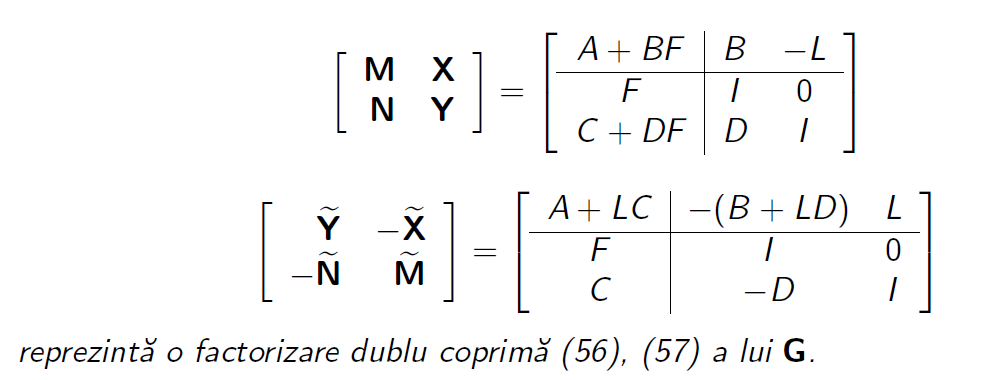. Atunci J va avea forma $J=\left\lbrack \begin{array}{ccc}
A+\textrm{BF}+\textrm{LC}+\textrm{LDF} & -L & B+\textrm{LD}\\
F & 0 & I\\
-\left(C+\textrm{DF}\right) & I & -D
\end{array}\right\rbrack$

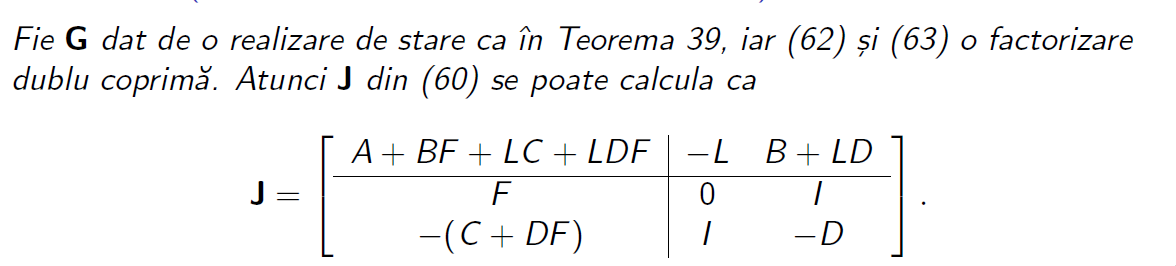

Observam ceva interesant? Daca fac $Q=0$, atunci $\textrm{TLFi}\left(J,Q\right)=J_{11} +J_{12} {Q\left(I-J_{22} Q\right)}^{-1} J_{21}$. Daca inlocuim pe $Q=0$ o sa avem $\textrm{TLFi}\left(J,0\right)=J_{11} =\left\lbrack \begin{array}{cc}
A+\textrm{BF}+LC+\textrm{LDF} & -L\\
F & 0
\end{array}\right\rbrack$care este **Compensatorul Kalman de la TSA**

## **Aici intra partea 2**

Din exemplul nostru, $\left(A,B\right)$ ctrb $\to$ alocabila, adica pot aloca polii unde vreau eu folosind un $F$, adica $\Lambda \left(A+\textrm{BF}\right)\in {\mathbb{C}}_-$. Pentru $F$ real, spectru simetric

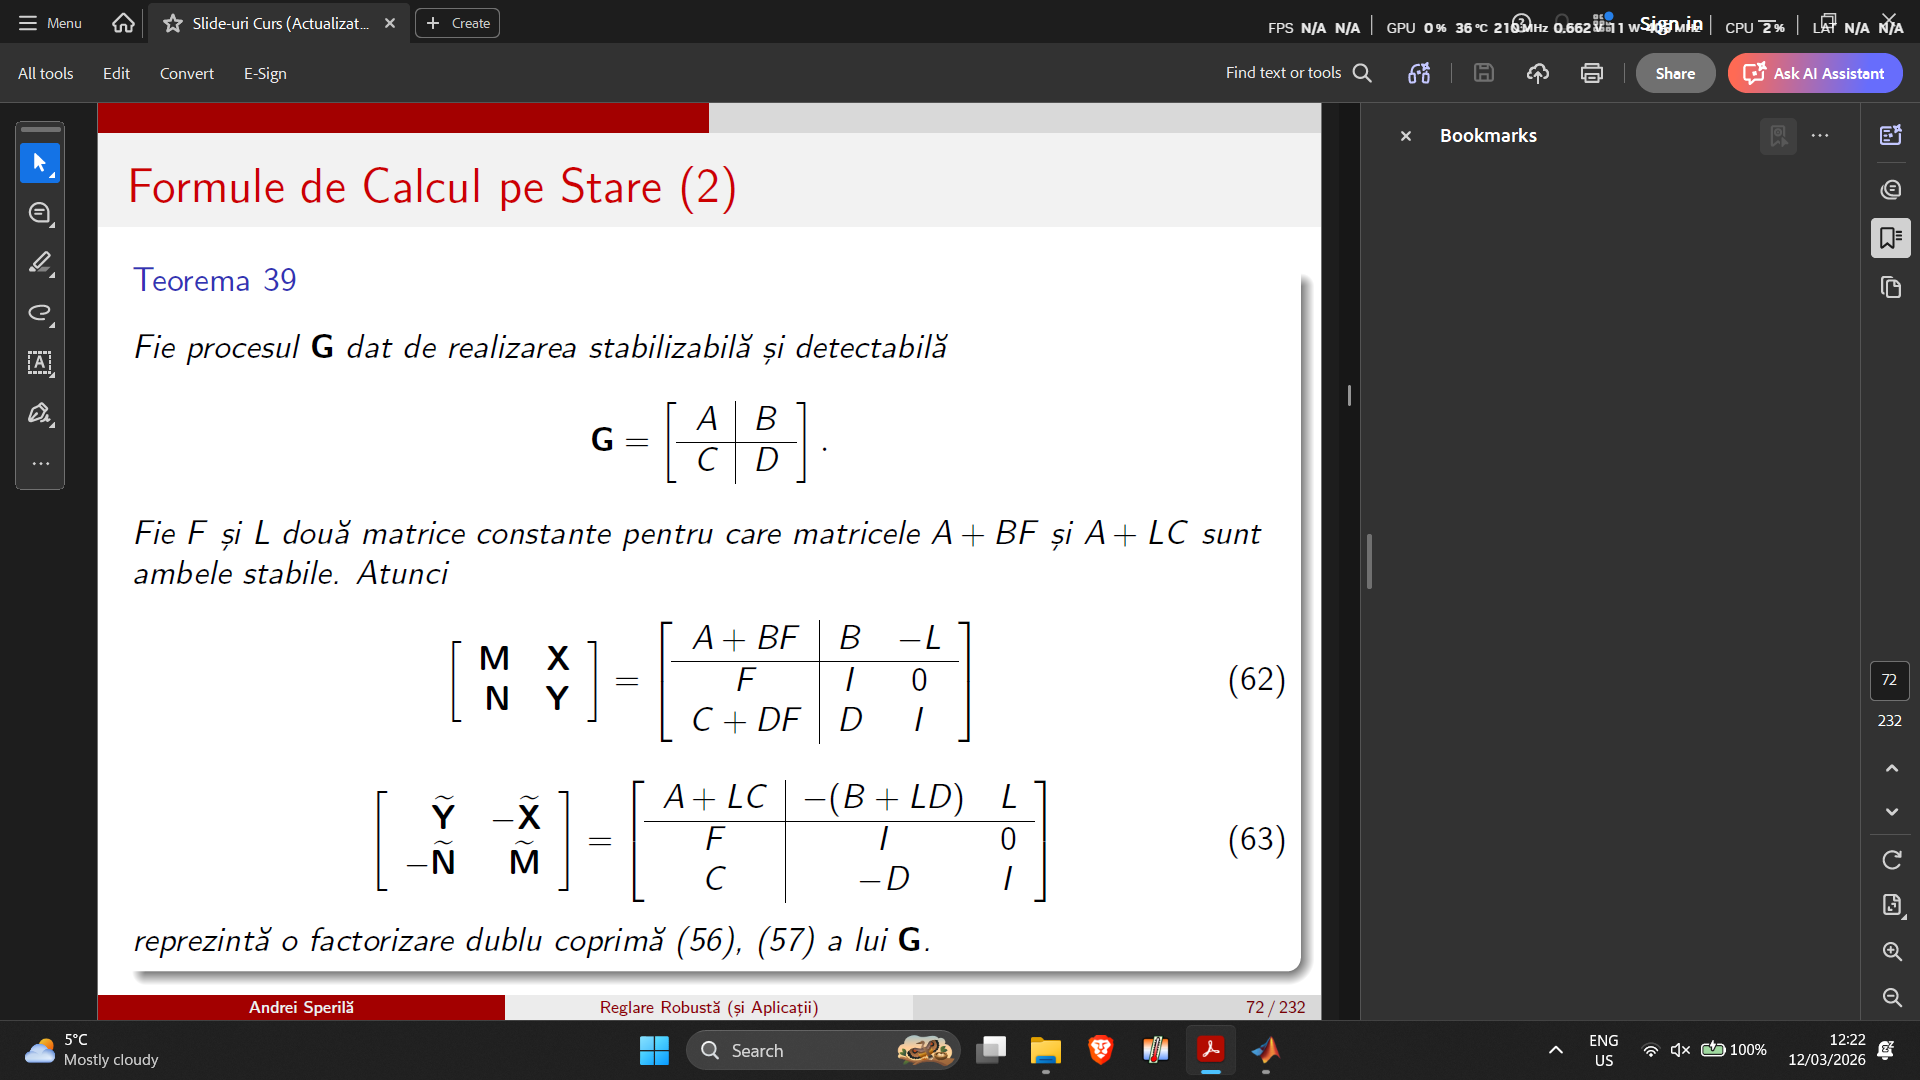

Unde $F\;\textrm{si}\;L$ asigura $\Lambda \left(A+\textrm{BF}\right)\;\textrm{si}\;\Lambda \left(A+\textrm{LC}\right)\in {\mathbb{C}}_-$

F = -place(A,B,[-1 -1 -1 -2])

F =     0.0619   -0.5573   -0.6686    0.5995
   -1.3168    0.0200   -0.5255   -1.2328
   -0.4201   -0.4484   -0.1518   -0.6583



L = -place(A',C',[-1 -1 -2 -2])'

L =     0.0055   -0.5781
   -0.2096   -0.4487
   -1.4690   -0.4577
   -1.3774   -0.3476



disp('Valori proprii ale lui A+BF');

Valori proprii ale lui A+BF


eig(A + B*F)

ans =    -2.0000
   -1.0000
   -1.0000
   -1.0000



disp('Valori proprii ale lui A+LC');

Valori proprii ale lui A+LC


eig(A + L*C)

ans =    -2.0000
   -2.0000
   -1.0000
   -1.0000



MatStanga = [A + B*F B -L;
             F eye(3) zeros(3,2)
             C -D eye(2,2)]

MatStanga =    -2.9288    2.7449   -1.2797    0.3153    8.0000    5.0000    2.0000   -0.0055    0.5781
   -0.6155   -0.1241   -0.4083    0.1006    1.0000    1.0000    8.0000    0.2096    0.4487
    0.6584   -0.9370   -0.5632   -0.1076    3.0000    4.0000    3.0000    1.4690    0.4577
    2.3485   -3.3420    1.5581   -1.3839    3.0000    1.0000    6.0000    1.3774    0.3476
    0.0619   -0.5573   -0.6686    0.5995    1.0000         0         0         0         0
   -1.3168    0.0200   -0.5255   -1.2328         0    1.0000         0         0         0
   -0.4201   -0.4484   -0.1518   -0.6583         0         0    1.0000         0         0
    9.0000    7.0000    4.0000    1.0000   -2.0000   -8.0000   -7.0000    1.0000         0
    4.0000    7.0000    6.0000    9.0000   -3.0000   -5.0000   -4.0000         0    1.0000



MatDreapta = [A + L*C -(B + L*D) L
                F eye(3) zeros(3,2)
                C -D eye(2)]

MatDreapta =     1.7369    3.9916    3.5533   -2.1975   -6.2766   -2.1533    0.2741    0.0055   -0.5781
    0.3185   -0.6085   -1.5309    1.7518    0.7654    2.9206   -4.7377   -0.2096   -0.4487
   -8.0519  -11.4870   -4.6222   -0.5883    1.3111   10.0406    9.1139   -1.4690   -0.4577
   -7.7872  -11.0753   -2.5954   -2.5061    0.7977   11.7574    5.0324   -1.3774   -0.3476
    0.0619   -0.5573   -0.6686    0.5995    1.0000         0         0         0         0
   -1.3168    0.0200   -0.5255   -1.2328         0    1.0000         0         0         0
   -0.4201   -0.4484   -0.1518   -0.6583         0         0    1.0000         0         0
    9.0000    7.0000    4.0000    1.0000   -2.0000   -8.0000   -7.0000    1.0000         0
    4.0000    7.0000    6.0000    9.0000   -3.0000   -5.0000   -4.0000         0    1.0000


Acum definesc cele 8 matrici bloc

Tilda

Ytilde = ss(A + L*C, -(B + L*D), F, eye(3))


Ytilde =
 
  A = 
            x1       x2       x3       x4
   x1    1.737    3.992    3.553   -2.197
   x2   0.3185  -0.6085   -1.531    1.752
   x3   -8.052   -11.49   -4.622  -0.5883
   x4   -7.787   -11.08   -2.595   -2.506
 
  B = 
           u1      u2      u3
   x1  -6.277  -2.153  0.2741
   x2  0.7654   2.921  -4.738
   x3   1.311   10.04   9.114
   x4  0.7977   11.76   5.032
 
  C = 
            x1       x2       x3       x4
   y1  0.06189  -0.5573  -0.6686   0.5995
   y2   -1.317  0.01999  -0.5255   -1.233
   y3  -0.4201  -0.4484  -0.1518  -0.6583
 
  D = 
       u1  u2  u3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
Continuous-time state-space model.



Xtilde = -ss(A + L*C, L, F, zeros(3,2))


Xtilde =
 
  A = 
            x1       x2       x3       x4
   x1    1.737    3.992    3.553   -2.197
   x2   0.3185  -0.6085   -1.531    1.752
   x3   -8.052   -11.49   -4.622  -0.5883
   x4   -7.787   -11.08   -2.595   -2.506
 
  B = 
             u1        u2
   x1  0.005477   -0.5781
   x2   -0.2096   -0.4487
   x3    -1.469   -0.4577
   x4    -1.377   -0.3476
 
  C = 
             x1        x2        x3        x4
   y1  -0.06189    0.5573    0.6686   -0.5995
   y2     1.317  -0.01999    0.5255     1.233
   y3    0.4201    0.4484    0.1518    0.6583
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.



Ntilde = -ss(A + L*C, -(B + L*D),C, -D)


Ntilde =
 
  A = 
            x1       x2       x3       x4
   x1    1.737    3.992    3.553   -2.197
   x2   0.3185  -0.6085   -1.531    1.752
   x3   -8.052   -11.49   -4.622  -0.5883
   x4   -7.787   -11.08   -2.595   -2.506
 
  B = 
           u1      u2      u3
   x1  -6.277  -2.153  0.2741
   x2  0.7654   2.921  -4.738
   x3   1.311   10.04   9.114
   x4  0.7977   11.76   5.032
 
  C = 
       x1  x2  x3  x4
   y1  -9  -7  -4  -1
   y2  -4  -7  -6  -9
 
  D = 
       u1  u2  u3
   y1   2   8   7
   y2   3   5   4
 
Continuous-time state-space model.



Mtilde = ss(A + L*C, L, C, eye(2))


Mtilde =
 
  A = 
            x1       x2       x3       x4
   x1    1.737    3.992    3.553   -2.197
   x2   0.3185  -0.6085   -1.531    1.752
   x3   -8.052   -11.49   -4.622  -0.5883
   x4   -7.787   -11.08   -2.595   -2.506
 
  B = 
             u1        u2
   x1  0.005477   -0.5781
   x2   -0.2096   -0.4487
   x3    -1.469   -0.4577
   x4    -1.377   -0.3476
 
  C = 
       x1  x2  x3  x4
   y1   9   7   4   1
   y2   4   7   6   9
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



ML = [Ytilde, -Xtilde;
      -Ntilde, Mtilde]


ML =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12      x13      x14      x15      x16
   x1     1.737    3.992    3.553   -2.197        0        0        0        0        0        0        0        0        0        0        0        0
   x2    0.3185  -0.6085   -1.531    1.752        0        0        0        0        0        0        0        0        0        0        0        0
   x3    -8.052   -11.49   -4.622  -0.5883        0        0        0        0        0        0        0        0        0        0        0        0
   x4    -7.787   -11.08   -2.595   -2.506        0        0        0        0        0        0        0        0        0        0        0        0
   x5         0        0        0        0    1.737    3.992    3.553   -2.197        0        0        0        0        0        0        0        0
   x6         0        0        0        0   0.3185  -0.6085   -1.531    1.752 

size(ML)

State-space model with 5 outputs, 5 inputs, and 16 states.


NeTilda

M = ss(A + B*F, B, F, eye(3))


M =
 
  A = 
            x1       x2       x3       x4
   x1   -2.929    2.745    -1.28   0.3153
   x2  -0.6155  -0.1241  -0.4083   0.1006
   x3   0.6584   -0.937  -0.5632  -0.1076
   x4    2.348   -3.342    1.558   -1.384
 
  B = 
       u1  u2  u3
   x1   8   5   2
   x2   1   1   8
   x3   3   4   3
   x4   3   1   6
 
  C = 
            x1       x2       x3       x4
   y1  0.06189  -0.5573  -0.6686   0.5995
   y2   -1.317  0.01999  -0.5255   -1.233
   y3  -0.4201  -0.4484  -0.1518  -0.6583
 
  D = 
       u1  u2  u3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
Continuous-time state-space model.



N = ss(A + B*F, B, C + D*F, D)


N =
 
  A = 
            x1       x2       x3       x4
   x1   -2.929    2.745    -1.28   0.3153
   x2  -0.6155  -0.1241  -0.4083   0.1006
   x3   0.6584   -0.937  -0.5632  -0.1076
   x4    2.348   -3.342    1.558   -1.384
 
  B = 
       u1  u2  u3
   x1   8   5   2
   x2   1   1   8
   x3   3   4   3
   x4   3   1   6
 
  C = 
           x1      x2      x3      x4
   y1  -4.351   2.907  -2.604  -12.27
   y2  -4.078   3.635  0.7595   2.001
 
  D = 
       u1  u2  u3
   y1   2   8   7
   y2   3   5   4
 
Continuous-time state-space model.



X = ss(A + B*F, -L, F, zeros(3,2))


X =
 
  A = 
            x1       x2       x3       x4
   x1   -2.929    2.745    -1.28   0.3153
   x2  -0.6155  -0.1241  -0.4083   0.1006
   x3   0.6584   -0.937  -0.5632  -0.1076
   x4    2.348   -3.342    1.558   -1.384
 
  B = 
              u1         u2
   x1  -0.005477     0.5781
   x2     0.2096     0.4487
   x3      1.469     0.4577
   x4      1.377     0.3476
 
  C = 
            x1       x2       x3       x4
   y1  0.06189  -0.5573  -0.6686   0.5995
   y2   -1.317  0.01999  -0.5255   -1.233
   y3  -0.4201  -0.4484  -0.1518  -0.6583
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.



Y = ss(A + B*F, -L, C + D*F, eye(2))


Y =
 
  A = 
            x1       x2       x3       x4
   x1   -2.929    2.745    -1.28   0.3153
   x2  -0.6155  -0.1241  -0.4083   0.1006
   x3   0.6584   -0.937  -0.5632  -0.1076
   x4    2.348   -3.342    1.558   -1.384
 
  B = 
              u1         u2
   x1  -0.005477     0.5781
   x2     0.2096     0.4487
   x3      1.469     0.4577
   x4      1.377     0.3476
 
  C = 
           x1      x2      x3      x4
   y1  -4.351   2.907  -2.604  -12.27
   y2  -4.078   3.635  0.7595   2.001
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



MR = [M,X;
      N,Y]


MR =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12      x13      x14      x15      x16
   x1    -2.929    2.745    -1.28   0.3153        0        0        0        0        0        0        0        0        0        0        0        0
   x2   -0.6155  -0.1241  -0.4083   0.1006        0        0        0        0        0        0        0        0        0        0        0        0
   x3    0.6584   -0.937  -0.5632  -0.1076        0        0        0        0        0        0        0        0        0        0        0        0
   x4     2.348   -3.342    1.558   -1.384        0        0        0        0        0        0        0        0        0        0        0        0
   x5         0        0        0        0   -2.929    2.745    -1.28   0.3153        0        0        0        0        0        0        0        0
   x6         0        0        0        0  -0.6155  -0.1241  -0.4083   0.1006 

size(MR)

State-space model with 5 outputs, 5 inputs, and 16 states.


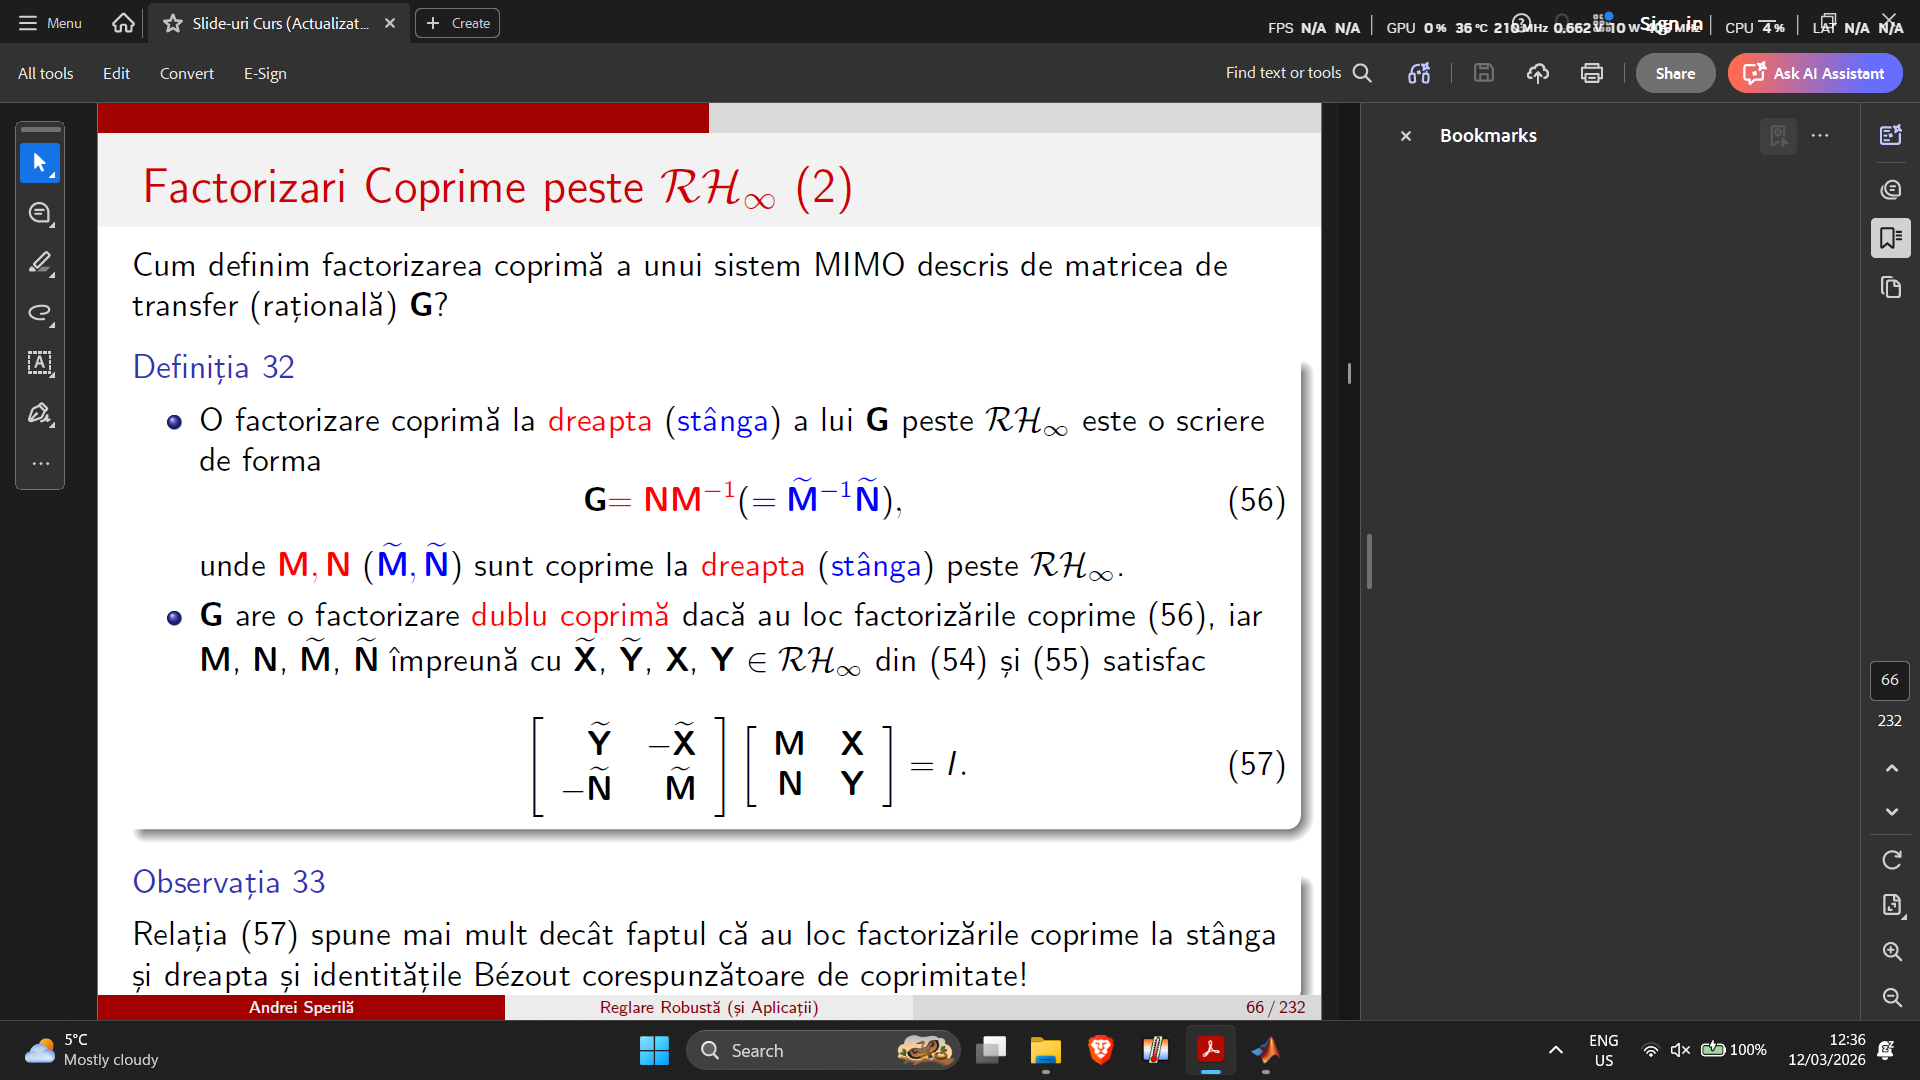

Ma pot uita la $G*M-N$ si $\tilde{M} *G-\tilde{N}$ pentru a vedea daca chiar este coprima factorizarea $G={\textrm{NM}}^{-1} ={\tilde{M} }^{-1} \tilde{\;N}$

G = ss(A,B,C,D)


G =
 
  A = 
       x1  x2  x3  x4
   x1   4   8   7   3
   x2   4   4   2   6
   x3   7   2   4   5
   x4   6   1   5   2
 
  B = 
       u1  u2  u3
   x1   8   5   2
   x2   1   1   8
   x3   3   4   3
   x4   3   1   6
 
  C = 
       x1  x2  x3  x4
   y1   9   7   4   1
   y2   4   7   6   9
 
  D = 
       u1  u2  u3
   y1   2   8   7
   y2   3   5   4
 
Continuous-time state-space model.



norm(G * M - N, 'inf')

ans = 2.9776e-13


norm(Mtilde * G - Ntilde, 'inf')

ans = 2.0463e-12

Acum verific Bezout

norm(ML * MR - eye(5), 'inf')

ans = 1.2428e-12


norm(MR * ML - eye(5), 'inf')

ans = 1.8643e-12

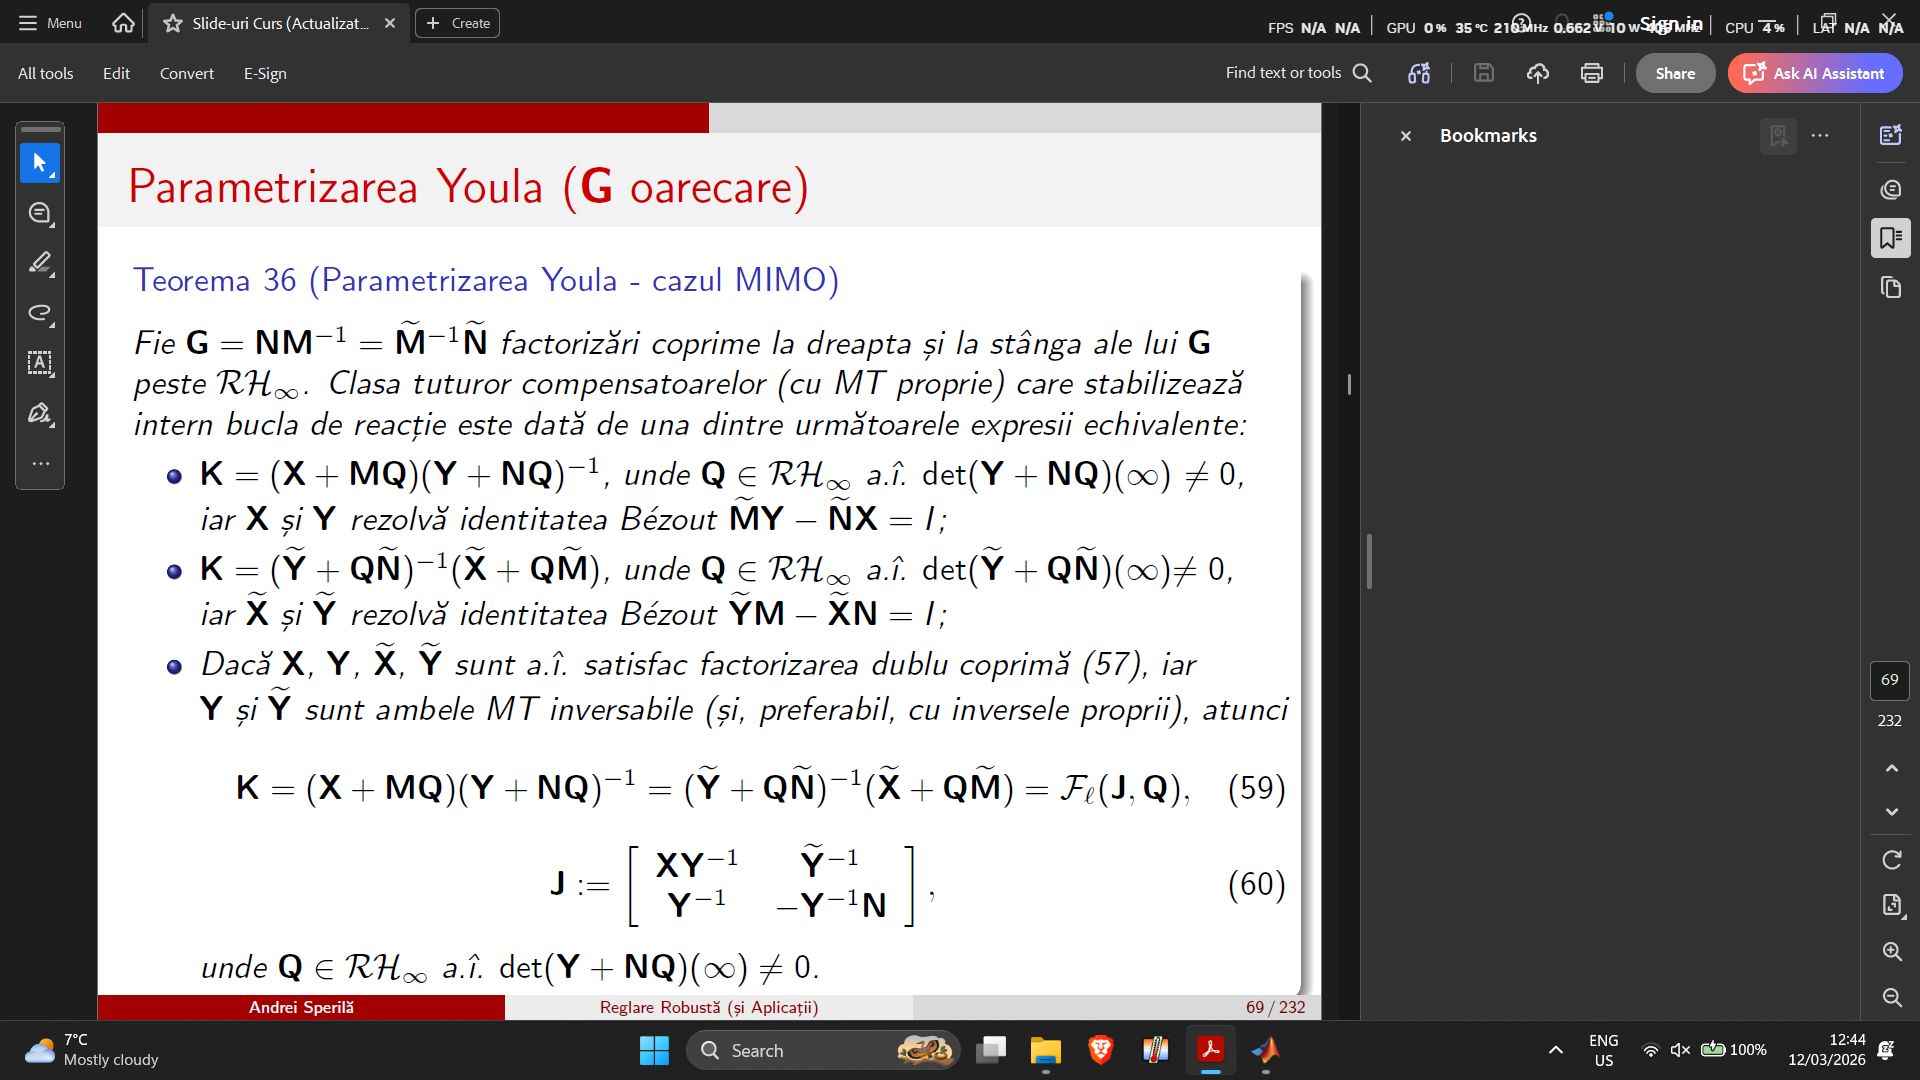

#### Practic este TLFi intre J si K, J sus si K jos

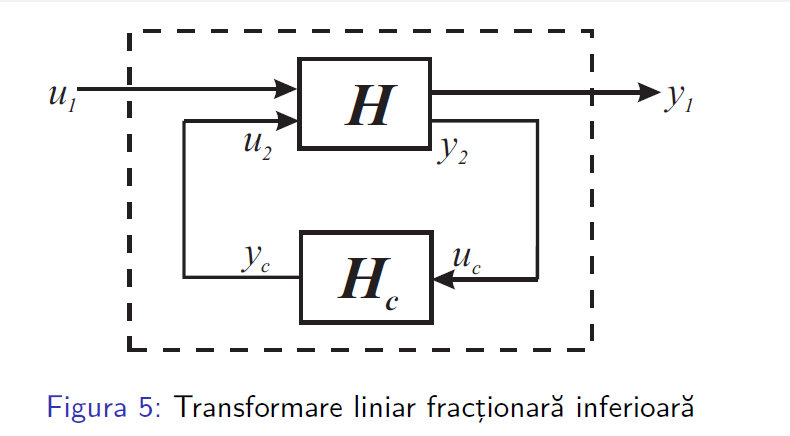

J = ss(A + B*F + L*C + L*D*F, [-L, B + L*D], ...
    [F; -(C + D*F)], [zeros(3,2), eye(3,3);eye(2,2), -D])


J =
 
  A = 
            x1       x2       x3       x4
   x1  -0.5949   0.6596   -1.733  -0.9089
   x2    2.127   -2.364  -0.2033    1.775
   x3    8.916   -6.871    2.914       17
   x4    9.759   -8.609    4.881    14.82
 
  B = 
              u1         u2         u3         u4         u5
   x1  -0.005477     0.5781      6.277      2.153    -0.2741
   x2     0.2096     0.4487    -0.7654     -2.921      4.738
   x3      1.469     0.4577     -1.311     -10.04     -9.114
   x4      1.377     0.3476    -0.7977     -11.76     -5.032
 
  C = 
            x1       x2       x3       x4
   y1  0.06189  -0.5573  -0.6686   0.5995
   y2   -1.317  0.01999  -0.5255   -1.233
   y3  -0.4201  -0.4484  -0.1518  -0.6583
   y4    4.351   -2.907    2.604    12.27
   y5    4.078   -3.635  -0.7595   -2.001
 
  D = 
       u1  u2  u3  u4  u5
   y1   0   0   1   0   0
   y2   0   0   0   1   0
   y3   0   0   0   0   1
   y4   1   0  -2  -8  -7
   y5   0   1  -3  -5  -4
 
Continuous-time state-space model.


Q = zeros(3,2)

Q =      0     0
     0     0
     0     0



Kc = lft(J,Q) % strict propriu, conexiune bine definita


Kc =
 
  A = 
            x1       x2       x3       x4
   x1  -0.5949   0.6596   -1.733  -0.9089
   x2    2.127   -2.364  -0.2033    1.775
   x3    8.916   -6.871    2.914       17
   x4    9.759   -8.609    4.881    14.82
 
  B = 
              u1         u2
   x1  -0.005477     0.5781
   x2     0.2096     0.4487
   x3      1.469     0.4577
   x4      1.377     0.3476
 
  C = 
            x1       x2       x3       x4
   y1  0.06189  -0.5573  -0.6686   0.5995
   y2   -1.317  0.01999  -0.5255   -1.233
   y3  -0.4201  -0.4484  -0.1518  -0.6583
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.



eig(Kc) % depinde cum nimeresti, de obicei nu este stabil

ans =    17.8815
    0.2856
   -1.0000
   -2.3889


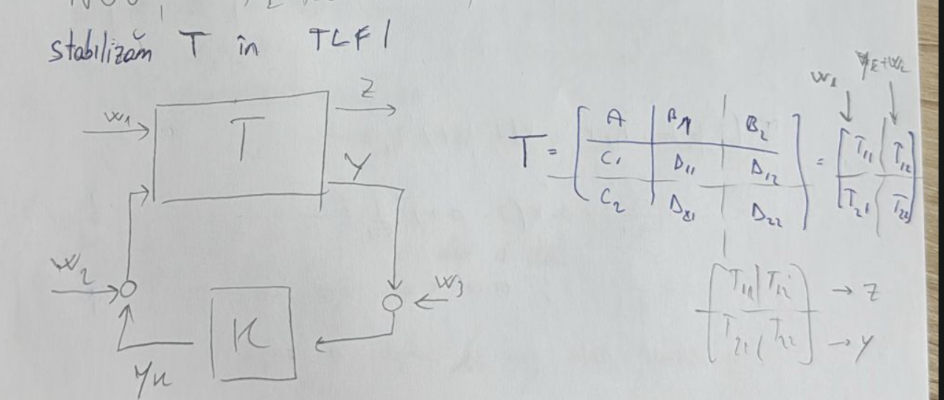

**Remarca: **Ce este cu linie punctata sunt pentru state-space

Egalitatea $\left\lbrack \begin{array}{ccc}
A & B_1  & B_2 \\
C_1  & D_{11}  & D_{12} \\
C_2  & D_{21}  & D_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
T_{11}  & T_{12} \\
T_{21}  & T_{22} 
\end{array}\right\rbrack$ are loc $\Leftrightarrow D_{22} \;\textrm{conectat}\;\textrm{la}\;K$

Fie $K=\left\lbrack \begin{array}{cc}
A_K  & B_K \\
C_K  & D_K 
\end{array}\right\rbrack$. Daca $\left\lbrace \begin{array}{l}
\left(A,B_2 \right)\;\textrm{stabilizabil}\\
\left(C_2 ,A\right)\;\textrm{detectabil}\\
\left(A_K ,B_K \right)\;\textrm{stabilizabil}\\
\left(C_K ,A_K \right)\;\textrm{detectabil}
\end{array}\right.\Rightarrow$ stabilizarea pe stare in TLFi **este echivalenta** cu stabilizarea I/O in TFLi sau intre $T_{22} \;\textrm{si}\;K$. Se poate face astfel incat toti polii instabili ai lui $T$ sa fie in $T_{22}$

In plus, $\left\lbrack \begin{array}{cc}
I & -D_{22} \\
-D_K  & I
\end{array}\right\rbrack$ inversabila

In acest sens, avem $\left\lbrack \begin{array}{c}
z\\
y\\
y_K 
\end{array}\right\rbrack =T_{\textrm{cl}} \left\lbrack \begin{array}{c}
w_1 \\
w_2 \\
w_3 
\end{array}\right\rbrack$ cu $T_{{\textrm{cl}}_{11} } =\textrm{TLFi}\left(T,K\right)=T_{11} +T_{12} {K\left(I-T_{22} K\right)}^{-1} T_{21}$

Sa luam niste exemple: $T=\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
2 & 0 & 0\\
3 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
3
\end{array}\right\rbrack \frac{1}{s-1}\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{2}{s-1} & 0\\
\frac{3}{s-1} & 0
\end{array}\right\rbrack$

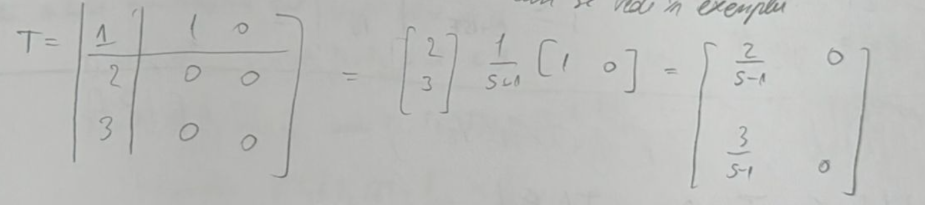

Aici se vede ca $T_{22}$ nu poate vede nimic. Pentru a ne convinge, facem $\textrm{TLFi}\left(T,K\right)=T_{11} +T_{12} {K\left(I-T_{22} K\right)}^{-1} T_{21} =\frac{2}{s-1}+0*{K\left(I-0*K\right)}^{-1} \frac{3}{s-1}$=$\frac{2}{s-1}$ care este mereu instabil, orice K as lua eu (face bum)

#### Un ale exemplu


$$T=\left\lbrack \begin{array}{ccc}
1 & 1 & 2\\
2 & 0 & 0\\
3 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
3
\end{array}\right\rbrack \frac{1}{s-1}\left\lbrack \begin{array}{cc}
1 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{2}{s-1} & \frac{4}{s-1}\\
\frac{3}{s-1} & \frac{6}{s-1}
\end{array}\right\rbrack$$


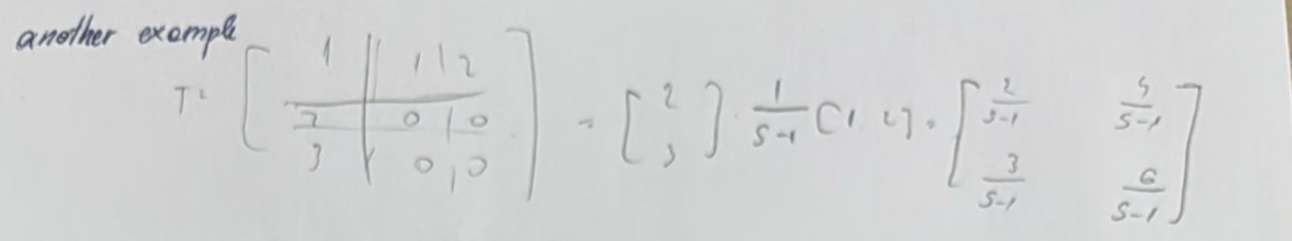

$T_{22} =\frac{6}{s-1}$. Deci putem doar sa stabilizan pe el. Fie un q astfel incat $1-\frac{6*q}{s-1}=\frac{s-1-6q}{s-1}$ sa aiba zero stabil. Pentru $q=-1\;\textrm{avem}\;\frac{s+5}{s-1}$ care are zero stabil,adica polul in bucla inchisa

Cum reprezentam asta pe stare? Uite asa:

$\left\lbrace \begin{array}{l}
\Sigma_T \left\lbrace \begin{array}{l}
\dot{x} =x+u_1 +2u_2 \\
y_1 =2x\\
y_2 =3x
\end{array}\right.\\
\Sigma_{\textrm{cl}} \left\lbrace \begin{array}{l}
\dot{x} =x+w_1 +2\left(w_2 +y_k \right)\\
z=2x\\
y_k =-w_3 -3x
\end{array}\right.
\end{array}\right.$, unde $\left\lbrace \begin{array}{l}
u_1 =w_1 \\
u_2 =w_2 +y_k \\
y_1 =z
\end{array}\right.$

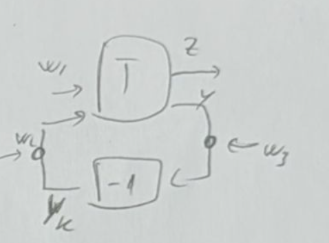

Cum stabilizeaza:

T_cl = feedback(G,-Kc)


T_cl =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1       4       8       7       3  -6.929  -5.255   -8.28  -2.685
   x2       4       4       2       6  -4.615  -4.124  -2.408  -5.899
   x3       7       2       4       5  -6.342  -2.937  -4.563  -5.108
   x4       6       1       5       2  -3.652  -4.342  -3.442  -3.384
   x5   2.263   4.008   3.447   5.197  -5.192  -1.264  -4.726  -4.882
   x6   3.682   4.608   3.531   4.248  -4.297  -4.733  -3.939  -4.148
   x7   15.05   13.49   8.622   5.588  -14.39  -14.42  -9.185  -5.696
   x8   13.79   12.08   7.595   4.506  -11.44  -15.42  -6.037   -5.89
 
  B = 
          u1     u2     u3
   x1      8      5      2
   x2      1      1      8
   x3      3      4      3
   x4      3      1      6
   x5  1.723  2.847  2.274
   x6  1.765  3.921  3.262
   x7  4.311  14.04  12.11
   x8  3.798  12.76  11.03
 
  C = 
           x1      x2      x3      x4      x5      x6      x7      x8
   y1       9       7 

disp('Valorile proprii ale buclei inchise')

Valorile proprii ale buclei inchise


eig(T_cl) % sa traiasca Principiul Separatiei

ans =   -2.0000 + 0.0000i
  -2.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i



disp('Valori proprii ale luI A+BF')

Valori proprii ale luI A+BF


eig(A+B*F)

ans =    -2.0000
   -1.0000
   -1.0000
   -1.0000



disp('Valori proprii ale lui A+LC')

Valori proprii ale lui A+LC


eig(A+L*C)

ans =    -2.0000
   -2.0000
   -1.0000
   -1.0000


Se poate observa ca $\Lambda \left(A+\textrm{BF}\right)\;\textrm{si}\;\Lambda \left(A+\textrm{LC}\right)$ sunt in $\textrm{eig}\left(T_{\textrm{cl}} \right)$

Aici se schimba Q ala

Q = tf(1,[1 3]) * randi(9,3,2)


Q =
 
  From input 1 to output...
         3
   1:  -----
       s + 3
 
         1
   2:  -----
       s + 3
 
         7
   3:  -----
       s + 3
 
  From input 2 to output...
         4
   1:  -----
       s + 3
 
         5
   2:  -----
       s + 3
 
         6
   3:  -----
       s + 3
 
Continuous-time transfer function.



K = lft(J,Q)


K =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1  -0.5949   0.6596   -1.733  -0.9089    4.766    8.557
   x2    2.127   -2.364  -0.2033    1.775    6.987     2.69
   x3    8.916   -6.871    2.914       17   -19.44   -27.53
   x4    9.759   -8.609    4.881    14.82   -12.34   -23.04
   x5     17.4   -11.63    10.42    49.09      -66      -90
   x6    16.31   -14.54   -3.038   -8.005      -42      -64
 
  B = 
              u1         u2
   x1  -0.005477     0.5781
   x2     0.2096     0.4487
   x3      1.469     0.4577
   x4      1.377     0.3476
   x5          4          0
   x6          0          4
 
  C = 
            x1       x2       x3       x4       x5       x6
   y1  0.06189  -0.5573  -0.6686   0.5995     0.75        1
   y2   -1.317  0.01999  -0.5255   -1.233     0.25     1.25
   y3  -0.4201  -0.4484  -0.1518  -0.6583     1.75      1.5
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.
<a href="m


eig(K)

ans =  -122.4016
   16.4400
  -13.4834
    5.1989
    0.0243
   -1.0000



svd(eye(2) - D * K.d)

ans =      1
     1



T_cl = feedback(G, -K)


T_cl =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10
   x1        4       8       7       3  -6.929  -5.255   -8.28  -2.685   10.75   17.25
   x2        4       4       2       6  -4.615  -4.124  -2.408  -5.899      15   14.25
   x3        7       2       4       5  -6.342  -2.937  -4.563  -5.108     8.5    12.5
   x4        6       1       5       2  -3.652  -4.342  -3.442  -3.384      13   13.25
   x5    2.263   4.008   3.447   5.197  -5.192  -1.264  -4.726  -4.882   10.75   17.25
   x6    3.682   4.608   3.531   4.248  -4.297  -4.733  -3.939  -4.148      15   14.25
   x7    15.05   13.49   8.622   5.588  -14.39  -14.42  -9.185  -5.696     8.5    12.5
   x8    13.79   12.08   7.595   4.506  -11.44  -15.42  -6.037   -5.89      13   13.25
   x9       36      28      16       4     -36     -28     -16      -4      -3       0
   x10      16      28      24      36     -16     -28     -24     -36       0      -3
 
  B = 
           u1    


eig(T_cl)

ans =   -3.0000 + 0.0000i
  -3.0000 + 0.0000i
  -2.0000 + 0.0000i
  -2.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i


% observam ca se adauga modurile stabile din Q in T_cl
% fata de inainte
% principiul separatiei sa traiasca again

clear
close all
clc

Ok ok, posibil sa fi vazut ca am mentionat **Principiul Separatiei.** Ce naiba este ala va intrebati

#### ***Noi trebuie sa avem un sistem stabilizabil si detectabil pentru asta sa mearga***

Intr-un fel separam problema nostra principala in 2: determinarea unui observator (L ala) si determinarea lui F ala

O sa explic in detaliu de unde aceasta "imparteala" (vom considera $D=0$):

Ce scop avem noi: $u=-F\hat{x}$ sa mentinem stabilitatea sistemului in bucvla inchisa si a observatorului

Mai intai sa luam sistemul nostru original liniar pe stare:$\left\lbrace \begin{array}{l}
\dot{x} =\mathrm{Ax}+\mathrm{Bu}\\
y=\mathrm{Cx}
\end{array}\right.$

O sa mai luam si dinamica data de observator: $\dot{\hat{x} } =A\hat{x} +B\hat{u} +L\left(y-C\hat{x} \right)$. Stim ca $u=-F\hat{x} \Rightarrow \dot{\hat{x} } =A\hat{x} -\mathrm{BF}\hat{x} +\mathrm{Ly}-\mathrm{LC}\hat{x} =$$\left(A-\mathrm{BF}-\mathrm{LC}\right)\hat{x} +\mathrm{Ly}$ cu $u=-F\hat{x}$

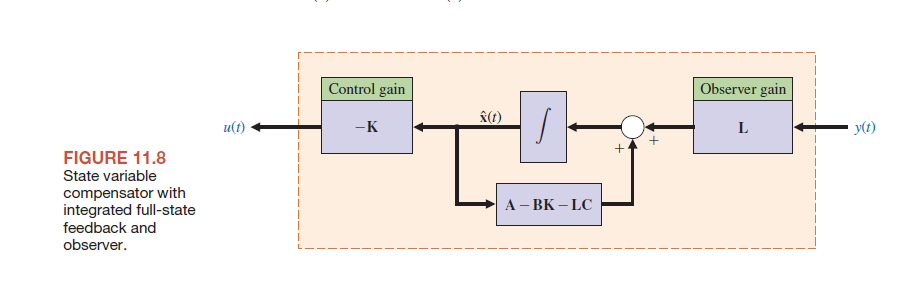

O sa rpesuunem ca $e=x-\hat{x} \Rightarrow \dot{e} =\dot{x} -\dot{\hat{x} \;} =\mathrm{Ax}+\mathrm{Bu}-A\hat{x} -\mathrm{Bu}-\mathrm{Ly}+\mathrm{LC}\hat{x} =$$A\left(x-\hat{x} \right)-\mathrm{Ly}+\mathrm{LC}\hat{x} =A\left(x-\hat{x} \right)-\mathrm{LCx}+\mathrm{LC}\hat{x} =\left(A-\mathrm{LC}\right)\left(x-\hat{x} \right)=$$\left(A-\mathrm{LC}\right)e$. Pe scurt, $\dot{e} =\left(A-\mathrm{LC}\right)e$. Doamne ajuta, eroarea nu depinde de intrare

Reluand modelul de stare liniar $\dot{x} =\mathrm{Ax}+\mathrm{Bu}=\mathrm{Ax}-\mathrm{BF}\hat{x}$ $\left(\mathrm{Stim}\;\mathrm{ca}\;u=-F\hat{x} \right)$. Mai stim ca $e=x-\hat{x} \Rightarrow \hat{x} =x-e$. De aici mai dezvoltam asa: $\dot{x} =\mathrm{Ax}-\mathrm{BF}\left(x-e\right)=\mathrm{Ax}-\mathrm{BFx}+\mathrm{BFe}=\left(A-\mathrm{BF}\right)x+\mathrm{BFe}$

Reamintim ca $\dot{e} =\left(A-\mathrm{LC}\right)e$. Daca scriem $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{e} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A-\mathrm{BF} & \mathrm{BF}\\
0 & A-\mathrm{LC}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
e
\end{array}\right\rbrack$

Daca calculam valorile proprii ale sistemului in bucla inchisa, o sa fie reuniunea $\Lambda \left(A-\mathrm{BF}\right)\bigcup \Lambda \left(A-\mathrm{LC}\right)$